load T2s.mat

vCrops = [-0.8 -0.2;-0.8 -0;-0.8 -0.4];
T2s.dt 

ans = 1×2 cell array
    {561×621×3 double}    {731×621×3 double}


data context

iph = 2

iph = 2

icr = 1

icr = 1

pln = T2s.dt{iph}(:,:,icr)

pln =   209.1145  210.4021  208.4943  206.3225  202.7762  199.8573  199.4814  201.4043  222.4078  255.8073  257.3047  257.6464  258.5348  261.1579  267.5256  280.5806  333.7577  393.0672  404.4582  412.0588  406.6764  400.5246  377.4755  223.6646  241.6182  245.9727  251.6344  253.8379  258.1064  260.9345  266.6348  282.6673  322.1829  382.2487  389.6539  387.6598  380.1790  244.7810  222.6616  215.9033  210.4082  205.8551  201.4668  198.8663  195.6888  193.4377  382.3077  405.5396  427.0382  438.2155
  215.9304  214.5814  211.2195  208.9867  206.1073  203.9582  205.0856  209.8582  240.6888  252.3205  253.0679  254.4649  258.7288  264.2588  274.6901  287.9829  304.5155  336.9263  373.8948  382.5504  377.3669  319.3686  221.0493  217.6212  226.1490  234.3137  243.7615  250.3948  257.7117  266.0616  275.9226  293.0349  309.6416  322.6298  315.3984  279.9603  247.0631  222.9543  218.3647  213.0751  208.4905  205.5564  202.3582  201.5880  199.8830  198.0651  196.0114  193.0473  386.5070  3

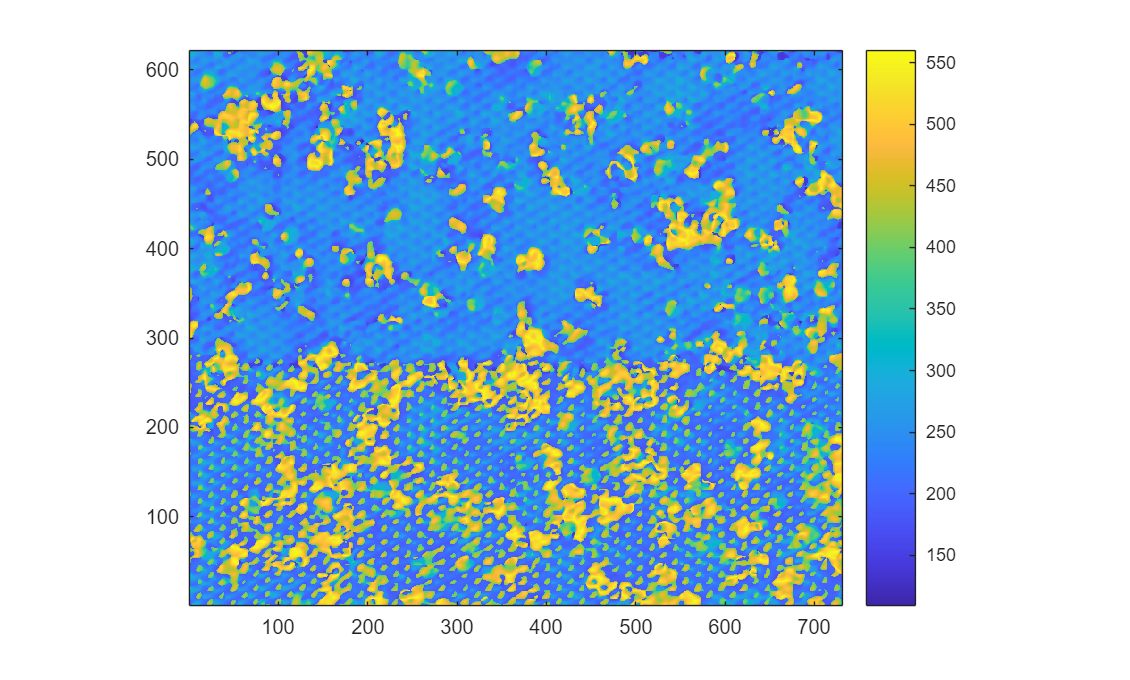

views(pln)
colorbar

Zint = [mapCD.dt(1).Z;mapCD.dt(2).Z]

Zint =     0.0894    0.0902    0.0914    0.0988    0.1061    0.1142    0.1210    0.1233    0.1253    0.1240    0.1231    0.1189    0.1153    0.1075    0.0994    0.0917    0.0852    0.0880    0.0920    0.0997    0.1079    0.1155    0.1232    0.1255    0.1269    0.1249    0.1226    0.1169    0.1108    0.1032    0.0957    0.0933    0.0933    0.0983    0.1049    0.1113    0.1177    0.1222    0.1259    0.1254    0.1231    0.1190    0.1140    0.1070    0.0981    0.0919    0.0879    0.0898    0.0960    0.1012
    0.0863    0.0944    0.0959    0.1043    0.1126    0.1202    0.1281    0.1323    0.1366    0.1358    0.1336    0.1274    0.1217    0.1115    0.1018    0.0943    0.0876    0.0924    0.0974    0.1061    0.1150    0.1225    0.1298    0.1336    0.1371    0.1364    0.1331    0.1254    0.1172    0.1076    0.0981    0.0955    0.0957    0.1027    0.1121    0.1198    0.1270    0.1313    0.1343    0.1347    0.1336    0.1304    0.1243    0.1150    0.1038    0.0962    0.0915    0.0926    0.0998  

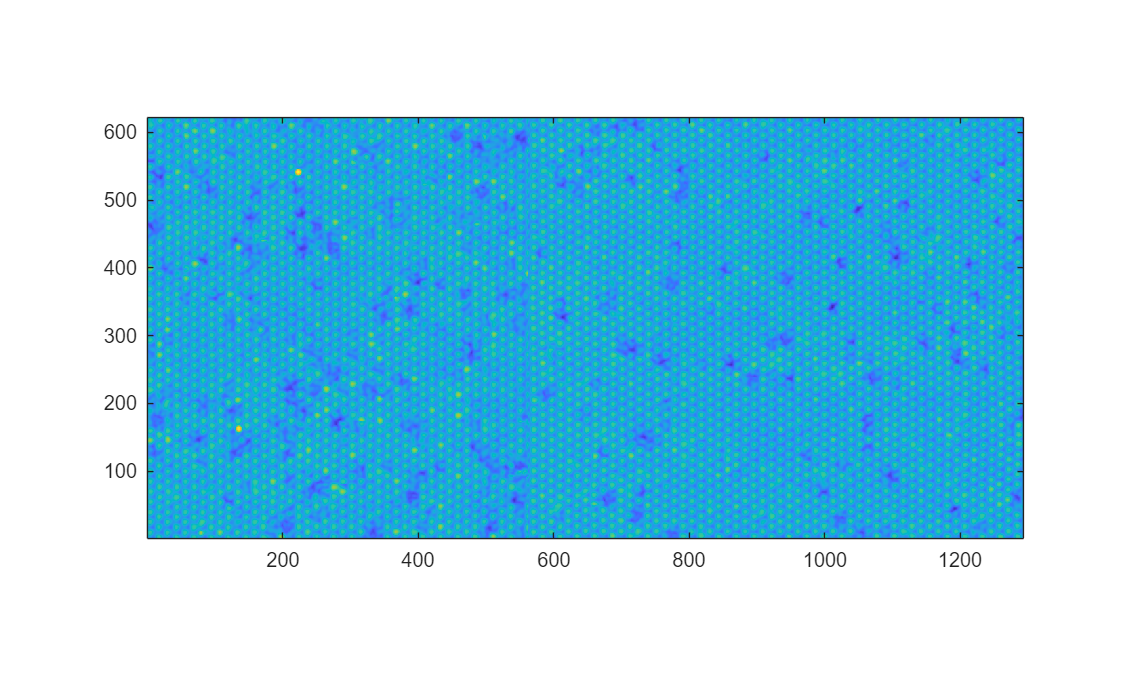

views(Zint)

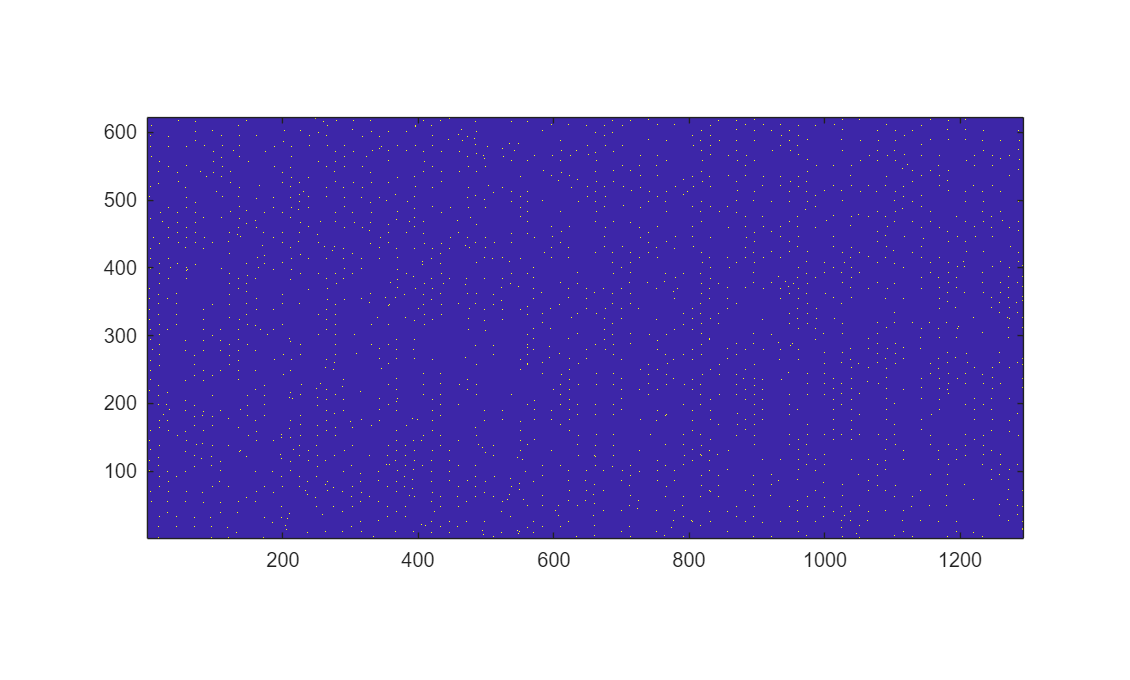

views(imregionalmax(Zint))

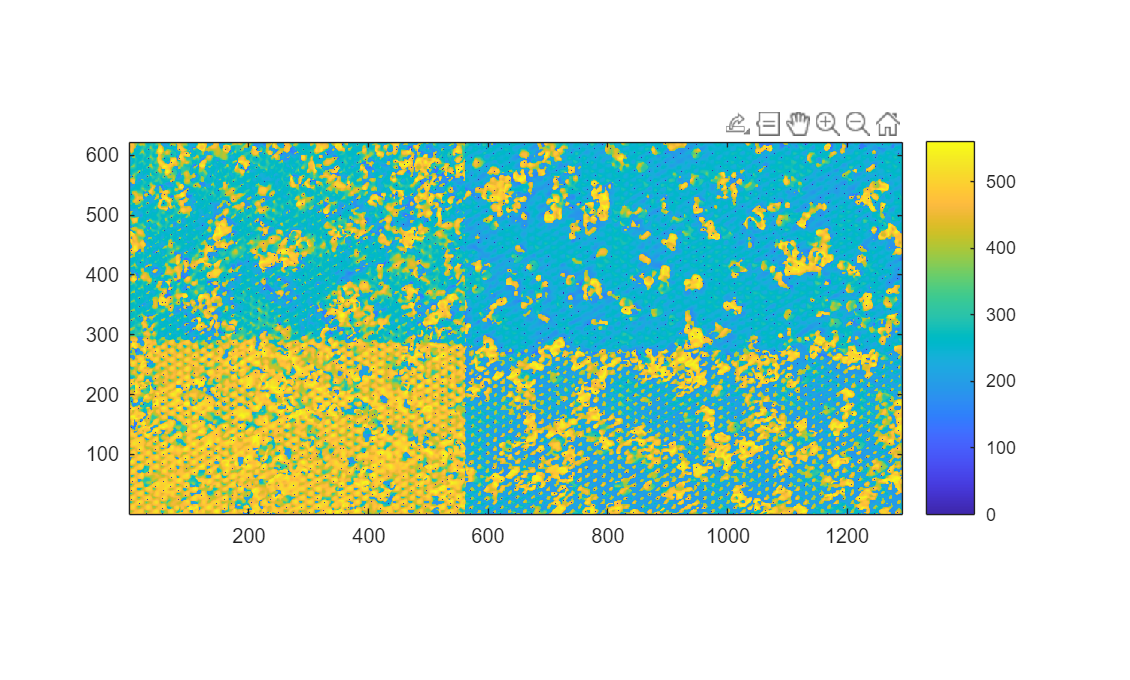

views(~imregionalmax(Zint).*[T2s.dt{1}(:,:,icr); T2s.dt{2}(:,:,icr)])
colorbar

icr = 3

icr = 3

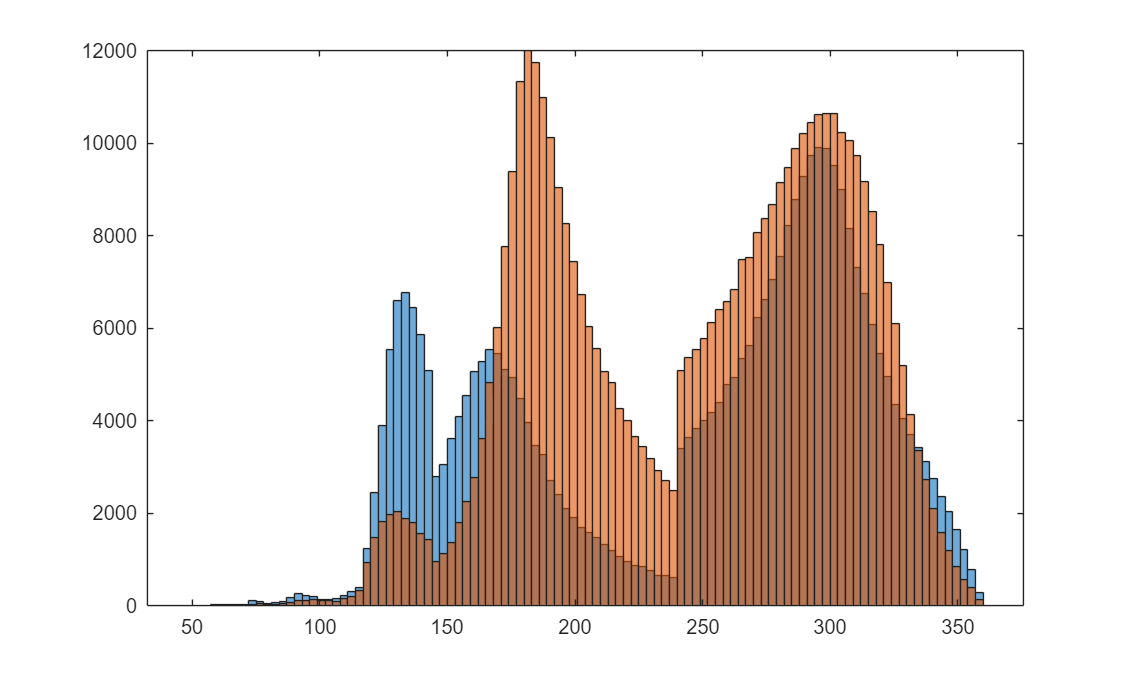

histogram(T2s.dt{1}(:,:,icr))
hold on
histogram(T2s.dt{2}(:,:,icr))
hold off

iph = 1

iph = 1

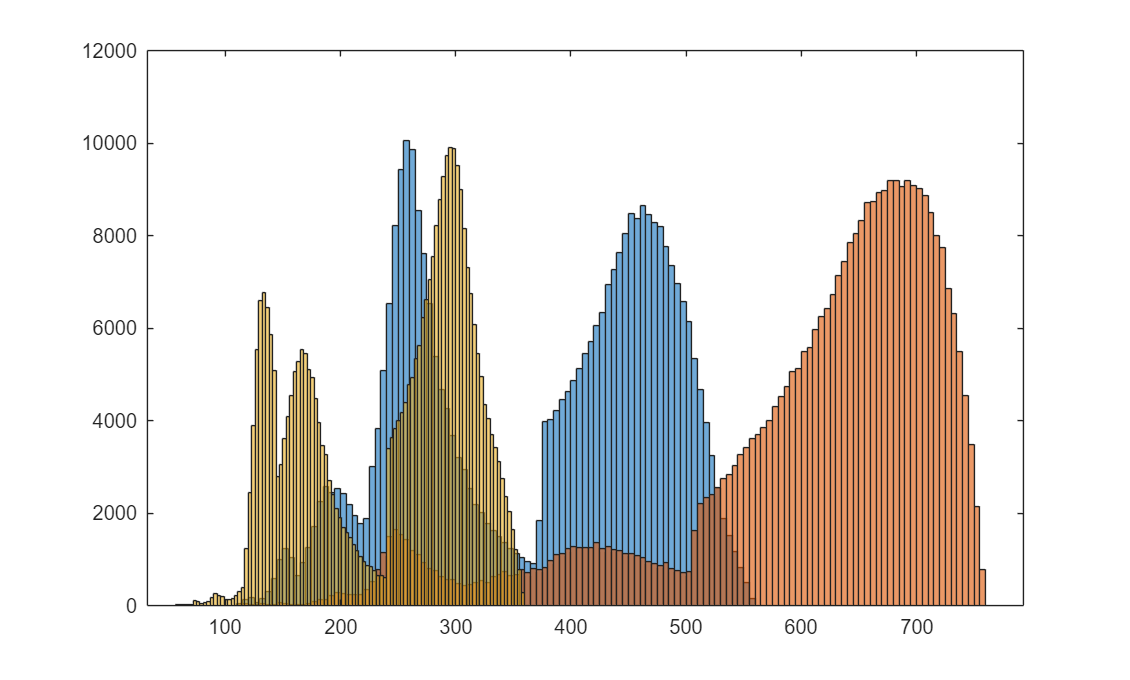

histogram(T2s.dt{iph}(:,:,1))
hold on
histogram(T2s.dt{iph}(:,:,2))
histogram(T2s.dt{iph}(:,:,3))
hold off

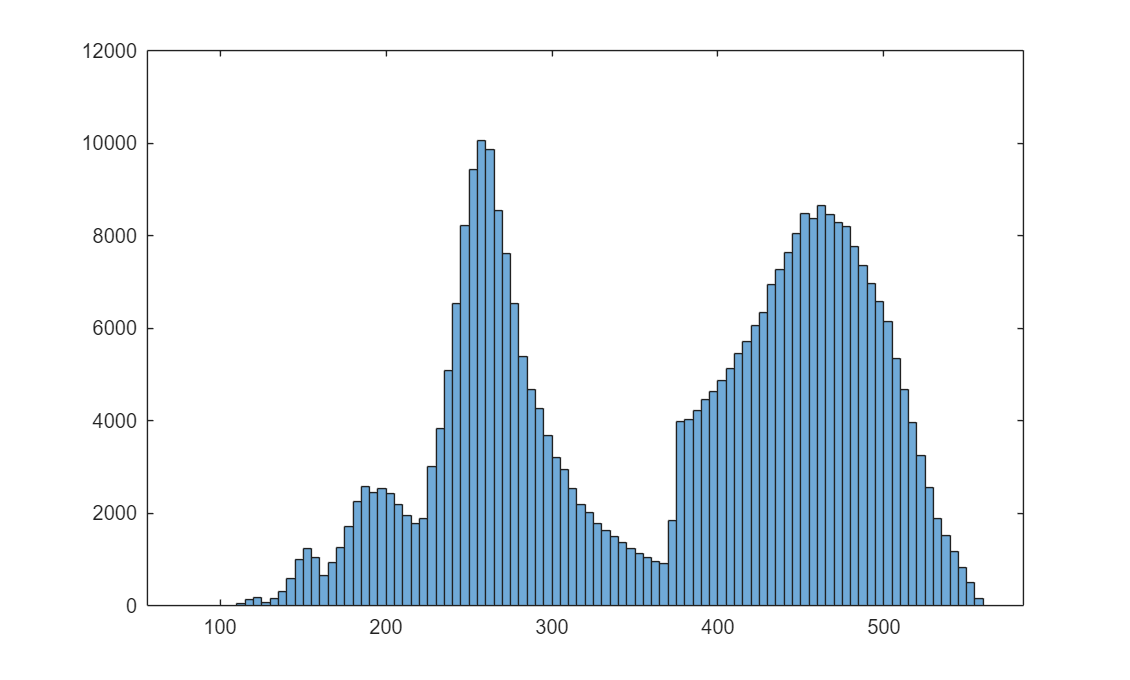

histogram(T2s.dt{1}(:,:,1))

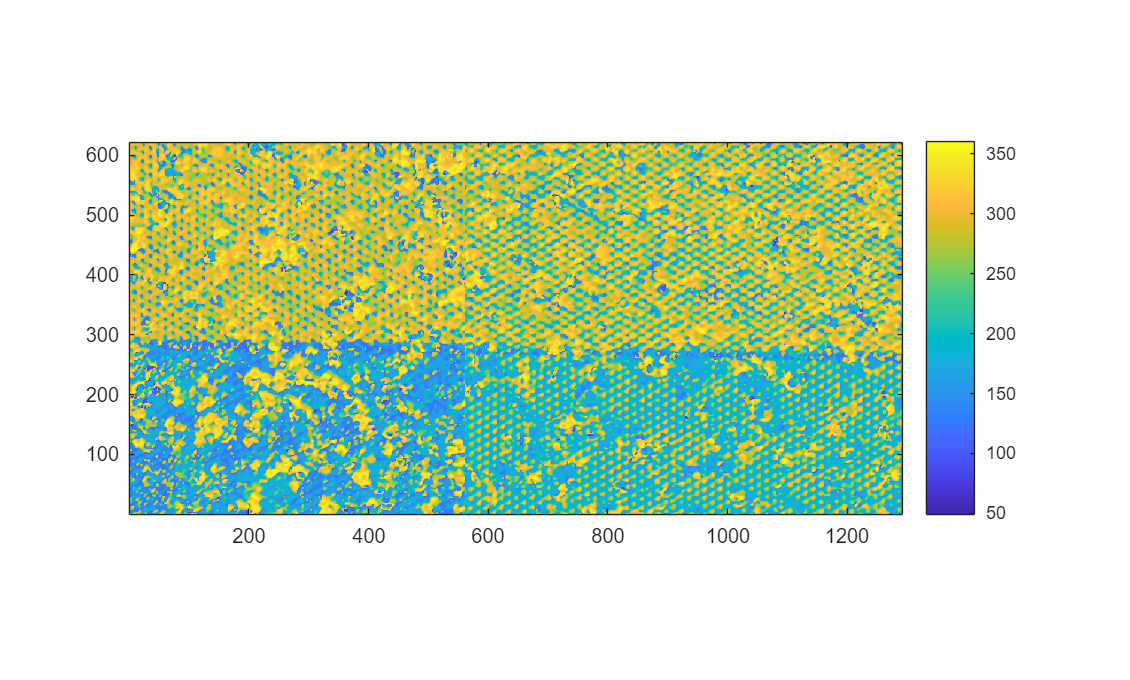

views([T2s.dt{1}(:,:,icr); T2s.dt{2}(:,:,icr)])
colorbar

size(T2s.dt{1}(:,:,icr))

ans =    561   621


Conclusiton: it is hard...